# **Purpose of this notebook is to find explore the dataset**

clearvars; clc

dataloc = 'E:/SP_cup/Dataset/ROBOVOX_SP_CUP_2024';  %Dataset location
% cd(dataloc)

single_channel_path = fullfile(dataloc,'data','single-channel');
single_enrolls = fullfile(single_channel_path,'enrollment') %fullfile in matlab makes a path

single_enrolls = 'E:\SP_cup\Dataset\ROBOVOX_SP_CUP_2024\data\single-channel\enrollment'

spk_labels = filenames2labels(single_enrolls, ExtractBefore='-', FileExtensions='.wav') %Extract the labels

spk_labels = 225×1 categorical array
     spk_10 
     spk_10 
     spk_10 
     spk_11 
     spk_11 
     spk_11 
     spk_12 
     spk_12 
     spk_12 
     spk_13 
     spk_13 
     spk_13 
     spk_14 
     spk_14 
     spk_14 
     spk_15 
     spk_15 
     spk_15 
     spk_16 
     spk_16 
     spk_16 
     spk_17 
     spk_17 
     spk_17 
     spk_18 
     spk_18 
     spk_18 
     spk_19 
     spk_19 
     spk_19 


spk_ids = unique(spk_labels)  %find out the unique labels

spk_ids = 75×1 categorical array
     spk_10 
     spk_11 
     spk_12 
     spk_13 
     spk_14 
     spk_15 
     spk_16 
     spk_17 
     spk_18 
     spk_19 
     spk_2 
     spk_20 
     spk_21 
     spk_22 
     spk_23 
     spk_24 
     spk_25 
     spk_26 
     spk_27 
     spk_28 
     spk_29 
     spk_3 
     spk_30 
     spk_31 
     spk_32 
     spk_33 
     spk_34 
     spk_35 
     spk_36 
     spk_37 


num_of_speakers = length(spk_ids) 

num_of_speakers = 75

numfiles_enroll = zeros(num_of_speakers,1);

for k = 1:num_of_speakers
    numfiles_enroll(k) = sum(spk_labels == spk_ids(k)); 
end

spk_file_count =   table(spk_ids, numfiles_enroll)  %So we have 3 files for each speaker (by observing the below graph)

spk_file_count = 75×2 table
    spk_ids    numfiles_enroll
    _______    _______________

    spk_10            3       
    spk_11            3       
    spk_12            3       
    spk_13            3       
    spk_14            3       
    spk_15            3       
    spk_16            3       
    spk_17            3       
    spk_18            3       
    spk_19            3       
    spk_2             3       
    spk_20            3       
    spk_21            3       
    spk_22            3       
    spk_23            3       
    spk_24            3       


If we are reading from a file by directly calling it's path, we can follow the below way

file_1 = 'spk_10-10_21_0_0_d2_ch5.wav';
[x,fs] = audioread(fullfile(single_enrolls,file_1));

Or else, we can create an audio data store object to listen, analyse audios. This takes all the audios from the folder and make it iterable. Just like an dataloader

ads_enr = audioDatastore(single_enrolls);
ads_enr.Labels = spk_labels

ads_enr =   audioDatastore with properties:

                       Files: {
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d2_ch5.wav';
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d3_ch5.wav';
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d4_ch5.wav'
                               ... and 222 more
                              }
                     Folders: {
                              'E:\SP_cup\Dataset\ROBOVOX_SP_CUP_2024\data\single-channel\enrollment'
                              }
                      Labels: [spk_10; spk_10; spk_10 ... and 222 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


[x, xinfo] = read(ads_enr) %read the next available audio from the collection --- Iterable

x =    -0.0074
   -0.0062
   -0.0047
   -0.0040
    0.0027
    0.0070
    0.0036
   -0.0014
    0.0019
    0.0053


xinfo = struct with fields:
    SampleRate: 16000
      FileName: 'E:\SP_cup\Dataset\ROBOVOX_SP_CUP_2024\data\single-channel\enrollment\spk_10-10_21_0_0_d2_ch5.wav'
         Label: spk_10


soundsc(x,xinfo.SampleRate)  % function to listen to the audio -- (audio, sampling rate)

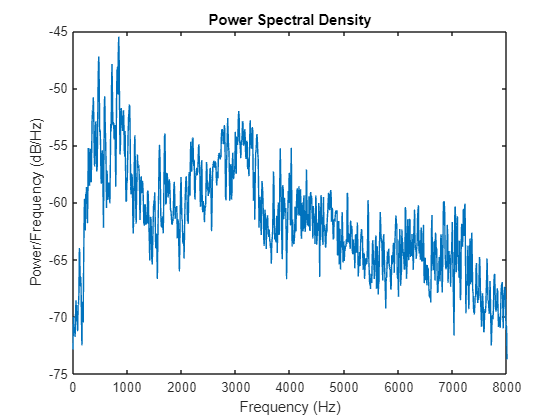

windowSize = 2056; % Size of the window for each segment
overlap = 1024;     % Overlap between consecutive segments
nfft = 2048;       % Number of points for FFT

[pxx_raw, f_raw] = pwelch(x, windowSize, overlap, nfft, fs);

figure;

% subplot(2,1,1);
% plot(x);

% subplot(2,1,2);
plot(f_raw, 10*log10(pxx_raw));
title('Power Spectral Density');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

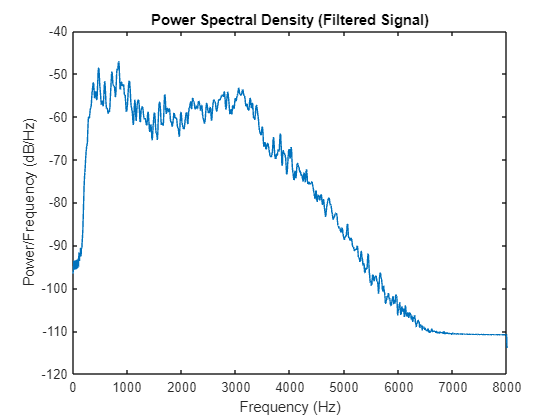

passband = [300, 3400]; % The passband frequencies in Hz
order = 4;            % Specify the filter order

[b, a] = butter(order, passband/(fs/2), 'bandpass');

filteredAudio = filter(b, a, x);   % Apply the bandpass filter to the audio signal

% Step 3: Calculate the PSD of the Filtered Signal
windowSize = 1024; % Size of the window for each segment
overlap = 512;     % Overlap between consecutive segments
nfft = 2048;       % Number of points for FFT

[pxx_filt, f_filt] = pwelch(filteredAudio, windowSize, overlap, nfft, fs);

plot(f_filt, 10*log10(pxx_filt));
title('Power Spectral Density (Filtered Signal)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

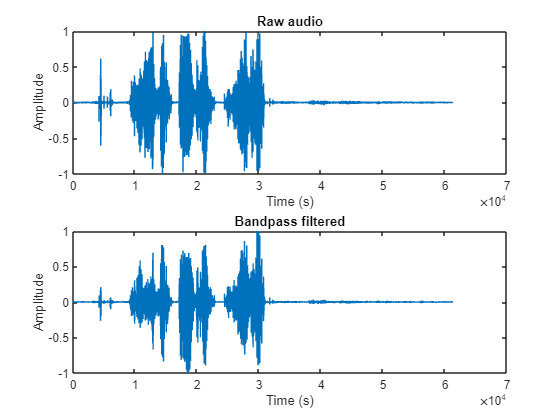

figure;

subplot(2,1,1);
plot(x);
title('Raw audio');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1 1]);

subplot(2,1,2)
plot(filteredAudio);
title('Bandpass filtered');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1 1]);

sound(x, fs);
audiowrite('Analyze_outputs/raw_audio.wav', x, fs);

sound(filteredAudio, fs);
audiowrite('Analyze_outputs/bandpass_human_voice.wav', x, fs);

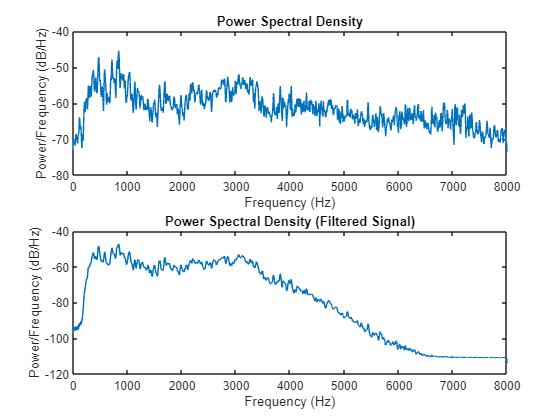

figure;

subplot(2,1,1);
plot(f_raw, 10*log10(pxx_raw));
title('Power Spectral Density');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
subplot(2,1,2);
plot(f_filt, 10*log10(pxx_filt));
title('Power Spectral Density (Filtered Signal)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');